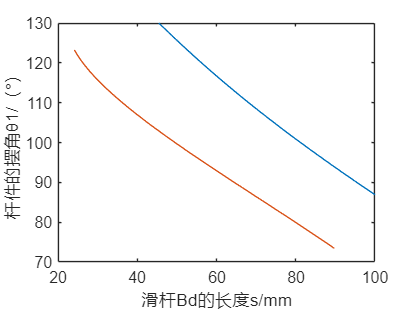

%% 运动学建模与求解
clear; clc;
l_BC = 54;
l_CE = 100;
l_DE = 84;

% 定义隐函数（以f(s,theta1)=0形式）
eq = @(s,theta1) l_DE.*sind(theta1) - l_BC - l_CE.*sqrt(1 - ((s - l_DE.*cosd(theta1))./l_CE).^2 );

% 指定变量范围并绘图
fimplicit(eq, [20 100 70 130]);
xlabel('s'); 
ylabel('\theta_1 (rad)');
ylabel('\theta_1');

hold on

BD_s=[
    0.0	89.7326
6.1052E-04	89.4725
8.6136E-04	89.4119
0.001	89.4082
0.0018	89.3821
0.002	89.3731
0.003	89.3229
0.004	89.2559
0.005	89.1685
0.006	89.0664
0.007	88.9357
0.008	88.8076
0.0083	88.7634
0.0085	88.7216
0.0088	88.6782
0.009	88.634
0.0093	88.5888
0.01	88.4466
0.011	88.2424
0.012	88.0194
0.013	87.7767
0.014	87.514
0.015	87.2309
0.016	86.9276
0.017	86.6029
0.018	86.2588
0.019	85.8904
0.02	85.5074
0.0208	85.2016
0.021	85.0968
0.0213	84.9907
0.022	84.6648
0.023	84.2114
0.024	83.7361
0.025	83.2383
0.026	82.7181
0.027	82.1743
0.028	81.6085
0.029	81.0165
0.03	80.4064
0.031	79.7623
0.032	79.0974
0.0323	78.9282
0.0328	78.5847
0.033	78.4106
0.0333	78.235
0.0335	78.0579
0.034	77.6991
0.035	76.9633
0.036	76.2028
0.037	75.4176
0.038	74.6076
0.039	73.7726
0.04	72.9137
0.041	72.0315
0.0415	71.5823
0.0418	71.356
0.042	71.1283
0.0423	70.8981
0.043	70.1918
0.044	69.2224
0.045	68.2257
0.046	67.2089
0.0468	66.4278
0.047	66.1646
0.0473	65.9001
0.0475	65.6344
0.048	65.0993
0.049	64.0159
0.0493	63.7432
0.0495	63.4703
0.0498	63.1949
0.05	62.9161
0.051	61.7741
0.052	60.6073
0.053	59.4219
0.054	58.2386
0.0543	57.8619
0.055	57.0118
0.0555	56.3857
0.056	55.7542
0.057	54.4833
0.0574	53.9771
0.058	53.2106
0.059	51.9167
0.0598	50.8348
0.06	50.5865
0.0603	50.2585
0.061	49.2528
0.0613	48.7875
0.062	47.8996
0.0623	47.4489
0.063	46.5504
0.0635	45.8644
0.064	45.1742
0.0646	44.3515
0.065	43.8036
0.0654	43.2496
0.066	42.4119
0.0663	42.0662
0.0665	41.7234
0.067	41.0331
0.0677	40.0952
0.068	39.6413
0.0683	39.1898
0.069	38.2563
0.0695	37.5646
0.0698	37.1073
0.07	36.8782
0.0703	36.4185
0.0705	36.1887
0.0707	35.9829
0.0711	35.3944
0.0713	35.1004
0.0716	34.6588
0.072	34.2213
0.0726	33.3534
0.0729	32.9253
0.0733	32.5026
0.0739	31.677
0.0746	30.8852
0.0752	30.1322
0.0759	29.4217
0.0765	28.7566
0.0772	28.1386
0.0778	27.5685
0.0785	27.0465
0.0791	26.572
0.0798	26.1437
0.0804	25.76
0.0811	25.419
0.0817	25.1184
0.0824	24.8558
0.0829	24.6479
0.0835	24.4676
0.0841	24.313
0.0845	24.2233
0.0847	24.1758
0.0849	24.1632
0.085	24.1562
0.0852	24.1533
0.0853	24.1524
0.0859	24.1616
0.0862	24.1733
0.0865	24.1875
0.0871	24.2304
0.0876	24.2931
0.0882	24.3762
0.0888	24.4805
0.0894	24.607
0.09	24.7567
0.0906	24.9308
0.0912	25.1305
0.0918	25.3572
0.0924	25.6121
0.0929	25.8964
0.0935	26.2112
0.0941	26.5574
0.0947	26.9357
0.0953	27.3467
0.0959	27.7904
0.0965	28.2665
0.0971	28.7744
0.0976	29.313
0.0982	29.8804
0.0988	30.4746
0.0994	31.0927
0.1	31.7314
0.1006	32.3866
0.1012	33.0538
0.1018	33.728
0.1024	34.4035
0.1029	35.0744
0.1035	35.7341
0.1041	36.3762
0.1047	36.9938
0.1053	37.5799
0.1059	38.1278
0.1065	38.631
0.1071	39.0831
0.1076	39.4785
0.1082	39.8121
0.1088	40.0794
0.1094	40.2769
0.11	40.4019
0.1106	40.4527
0.1112	40.4287
0.1118	40.3301
0.1124	40.1584
0.1129	39.9159
0.1135	39.6059
0.1141	39.2325
0.1147	38.8005
0.1153	38.3156
0.1159	37.7839
0.1165	37.2117
0.1171	36.6058
0.1176	35.973
0.1182	35.3202
0.1188	34.654
0.1194	33.981
0.12	33.3073
0.1206	32.6386
0.1212	31.9802
0.1218	31.3366
0.1224	30.7123
0.1229	30.1105
0.1235	29.5345
0.1241	28.9866
0.1247	28.4686
0.1253	27.9819
0.1259	27.5273
0.1265	27.1053
0.1271	26.7159
0.1276	26.3586
0.1282	26.033
0.1288	25.7381
0.1294	25.473
0.13	25.2364
0.1306	25.0272
0.1312	24.844
0.1318	24.6857
0.1324	24.551
0.1329	24.4388
0.1335	24.3482
0.1341	24.2783
0.1347	24.2284
0.1353	24.198
0.1359	24.1869
0.1365	24.1948
0.1371	24.2219
0.1376	24.2685
0.1382	24.335
0.1388	24.4221
0.1394	24.5305
0.14	24.6613
0.1406	24.8155
0.1412	24.9943
0.1418	25.1989
0.1424	25.4306
0.1429	25.6906
0.1435	25.9801
0.1441	26.3001
0.1447	26.6515
0.1453	27.0349
0.1459	27.4508
0.1465	27.8991
0.1471	28.3795
0.1476	28.8912
0.1482	29.433
0.1488	30.0031
0.1494	30.5991
0.15	31.2181
0.1506	31.8567
0.1512	32.5108
0.1518	33.1758
0.1524	33.8466
0.1529	34.5174
0.1535	35.1823
0.1541	35.8349
0.1547	36.4684
0.1553	37.0762
0.1559	37.6515
0.1565	38.1875
0.1571	38.6778
0.1576	39.1163
0.1582	39.4975
0.1588	39.8163
0.1594	40.0687
0.16	40.2511
0.1606	40.3613
0.1612	40.3976
0.1618	40.3596
0.1624	40.2478
0.1629	40.0639
0.1635	39.8101
0.1641	39.4901
0.1647	39.108
0.1653	38.6689
0.1659	38.1782
0.1665	37.6421
0.1671	37.0671
0.1676	36.4598
0.1682	35.827
0.1688	35.1756
0.1694	34.512
0.17	33.8426
0.1706	33.1736
0.1712	32.5104
0.1718	31.8582
0.1724	31.2215
0.1729	30.6044
0.1735	30.0104
0.1741	29.4422
0.1747	28.9022
0.1753	28.3922
0.1759	27.9134
0.1765	27.4666
0.1771	27.0521
0.1776	26.6699
0.1782	26.3197
0.1788	26.0007
0.1794	25.7121
0.18	25.4529
0.1806	25.2219
0.1812	25.0179
0.1818	24.8396
0.1824	24.6859
0.1829	24.5556
0.1835	24.4476
0.1841	24.361
0.1847	24.295
0.1853	24.2489
0.1859	24.2223
0.1865	24.2149
0.1871	24.2267
0.1876	24.2577
0.1882	24.3082
0.1888	24.3788
0.1894	24.4702
0.19	24.5831
0.1906	24.7185
0.1912	24.8776
0.1918	25.0614
0.1924	25.2713
0.1929	25.5083
0.1935	25.7738
0.1941	26.0688
0.1947	26.3945
0.1953	26.7514
0.1959	27.1403
0.1965	27.5614
0.1971	28.0147
0.1976	28.4997
0.1982	29.0156
0.1988	29.5608
0.1994	30.1337
0.2	30.7316];
Theta1=[
    0.0	73.4257
6.1052E-04	73.6037
8.6136E-04	73.6451
0.001	73.6477
0.0018	73.6655
0.002	73.6716
0.003	73.7059
0.004	73.7517
0.005	73.8113
0.006	73.8809
0.007	73.97
0.008	74.0573
0.0083	74.0874
0.0085	74.1158
0.0088	74.1454
0.009	74.1754
0.0093	74.2062
0.01	74.3028
0.011	74.4414
0.012	74.5926
0.013	74.757
0.014	74.9346
0.015	75.1257
0.016	75.3301
0.017	75.5486
0.018	75.7797
0.019	76.0267
0.02	76.2831
0.0208	76.4874
0.021	76.5573
0.0213	76.6281
0.022	76.8453
0.023	77.1469
0.024	77.4625
0.025	77.7924
0.026	78.1364
0.027	78.4953
0.028	78.8679
0.029	79.257
0.03	79.6574
0.031	80.0791
0.032	80.5137
0.0323	80.6242
0.0328	80.8484
0.033	80.9619
0.0333	81.0764
0.0335	81.1918
0.034	81.4254
0.035	81.904
0.036	82.398
0.037	82.9074
0.038	83.4322
0.039	83.9728
0.04	84.5285
0.041	85.0989
0.0415	85.3892
0.0418	85.5355
0.042	85.6827
0.0423	85.8315
0.043	86.288
0.044	86.9147
0.045	87.5594
0.046	88.2176
0.0468	88.7238
0.047	88.8944
0.0473	89.066
0.0475	89.2384
0.048	89.5859
0.049	90.2905
0.0493	90.4681
0.0495	90.6459
0.0498	90.8255
0.05	91.0074
0.051	91.754
0.052	92.5193
0.053	93.2998
0.054	94.0823
0.0543	94.3322
0.055	94.8977
0.0555	95.3156
0.056	95.7383
0.057	96.5933
0.0574	96.9355
0.058	97.4557
0.059	98.3394
0.0598	99.0843
0.06	99.256
0.0603	99.4834
0.061	100.1843
0.0613	100.5106
0.062	101.1366
0.0623	101.4563
0.063	102.0977
0.0635	102.5912
0.064	103.0914
0.0646	103.6925
0.065	104.0959
0.0654	104.5066
0.066	105.1331
0.0663	105.3937
0.0665	105.6532
0.067	106.1798
0.0677	106.904
0.068	107.2583
0.0683	107.6135
0.069	108.3567
0.0695	108.9157
0.0698	109.2894
0.07	109.478
0.0703	109.8592
0.0705	110.0512
0.0707	110.2239
0.0711	110.7226
0.0713	110.9744
0.0716	111.3561
0.072	111.7386
0.0726	112.5115
0.0729	112.9002
0.0733	113.2892
0.0739	114.0654
0.0746	114.8327
0.0752	115.5862
0.0759	116.3219
0.0765	117.0357
0.0772	117.7244
0.0778	118.385
0.0785	119.0148
0.0791	119.6115
0.0798	120.1733
0.0804	120.6984
0.0811	121.1853
0.0817	121.6328
0.0824	122.0398
0.0829	122.3744
0.0835	122.6746
0.0841	122.9401
0.0845	123.098
0.0847	123.1827
0.0849	123.2054
0.085	123.218
0.0852	123.2232
0.0853	123.2247
0.0859	123.2082
0.0862	123.1871
0.0865	123.1617
0.0871	123.0853
0.0876	122.9748
0.0882	122.8306
0.0888	122.6527
0.0894	122.4417
0.09	122.1979
0.0906	121.9219
0.0912	121.6143
0.0918	121.2757
0.0924	120.907
0.0929	120.5091
0.0935	120.0832
0.0941	119.6303
0.0947	119.1519
0.0953	118.6495
0.0959	118.1248
0.0965	117.5797
0.0971	117.0163
0.0976	116.4368
0.0982	115.844
0.0988	115.2405
0.0994	114.6292
0.1	114.0136
0.1006	113.3969
0.1012	112.7829
0.1018	112.1755
0.1024	111.5787
0.1029	110.9967
0.1035	110.4339
0.1041	109.8944
0.1047	109.3828
0.1053	108.9032
0.1059	108.4599
0.1065	108.0569
0.1071	107.6978
0.1076	107.3861
0.1082	107.1247
0.1088	106.9163
0.1094	106.7629
0.11	106.666
0.1106	106.6267
0.1112	106.6453
0.1118	106.7216
0.1124	106.8549
0.1129	107.0437
0.1135	107.2861
0.1141	107.5798
0.1147	107.9219
0.1153	108.309
0.1159	108.7376
0.1165	109.2038
0.1171	109.7035
0.1176	110.2323
0.1182	110.786
0.1188	111.3602
0.1194	111.9506
0.12	112.5531
0.1206	113.1634
0.1212	113.7777
0.1218	114.3923
0.1224	115.0036
0.1229	115.6083
0.1235	116.2033
0.1241	116.7859
0.1247	117.3534
0.1253	117.9034
0.1259	118.4338
0.1265	118.9425
0.1271	119.4279
0.1276	119.8884
0.1282	120.3225
0.1288	120.729
0.1294	121.1067
0.13	121.4548
0.1306	121.7723
0.1312	122.0585
0.1318	122.3128
0.1324	122.5345
0.1329	122.7234
0.1335	122.8789
0.1341	123.0008
0.1347	123.0889
0.1353	123.1429
0.1359	123.1628
0.1365	123.1486
0.1371	123.1003
0.1376	123.018
0.1382	122.9018
0.1388	122.7519
0.1394	122.5687
0.14	122.3525
0.1406	122.1038
0.1412	121.8231
0.1418	121.511
0.1424	121.1683
0.1429	120.7958
0.1435	120.3945
0.1441	119.9654
0.1447	119.5098
0.1453	119.0291
0.1459	118.5248
0.1465	117.9987
0.1471	117.4528
0.1476	116.8891
0.1482	116.31
0.1488	115.718
0.1494	115.1161
0.15	114.5071
0.1506	113.8945
0.1512	113.2815
0.1518	112.6721
0.1524	112.0699
0.1529	111.4792
0.1535	110.904
0.1541	110.3487
0.1547	109.8176
0.1553	109.3149
0.1559	108.845
0.1565	108.4119
0.1571	108.0195
0.1576	107.6715
0.1582	107.3712
0.1588	107.1214
0.1594	106.9247
0.16	106.7829
0.1606	106.6975
0.1612	106.6694
0.1618	106.6988
0.1624	106.7854
0.1629	106.9284
0.1635	107.1262
0.1641	107.377
0.1647	107.6781
0.1653	108.0267
0.1659	108.4194
0.1665	108.8526
0.1671	109.3225
0.1676	109.8248
0.1682	110.3553
0.1688	110.9098
0.1694	111.4839
0.17	112.0734
0.1706	112.6741
0.1712	113.2819
0.1718	113.8931
0.1724	114.5038
0.1729	115.1108
0.1735	115.7106
0.1741	116.3003
0.1747	116.8771
0.1753	117.4386
0.1759	117.9822
0.1765	118.5059
0.1771	119.0079
0.1776	119.4863
0.1782	119.9396
0.1788	120.3664
0.1794	120.7656
0.18	121.136
0.1806	121.4766
0.1812	121.7867
0.1818	122.0655
0.1824	122.3124
0.1829	122.5268
0.1835	122.7084
0.1841	122.8567
0.1847	122.9715
0.1853	123.0525
0.1859	123.0996
0.1865	123.1128
0.1871	123.0919
0.1876	123.0371
0.1882	122.9484
0.1888	122.826
0.1894	122.6702
0.19	122.4812
0.1906	122.2595
0.1912	122.0055
0.1918	121.7197
0.1924	121.4028
0.1929	121.0557
0.1935	120.6791
0.1941	120.274
0.1947	119.8415
0.1953	119.3829
0.1959	118.8997
0.1965	118.3933
0.1971	117.8657
0.1976	117.3188
0.1982	116.7547
0.1988	116.1758
0.1994	115.5848
0.2	114.9844];

plot(BD_s(:,2),Theta1(:,2))
xlabel('滑杆Bd的长度s/mm')
ylabel('杆件的摆角θ1/（°）')

hold off

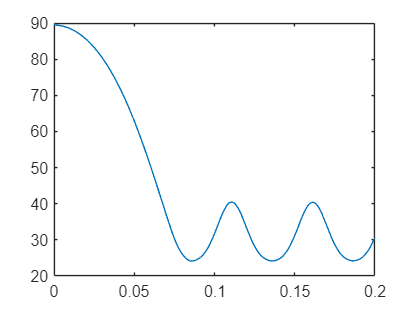

plot(BD_s(:,1),BD_s(:,2))

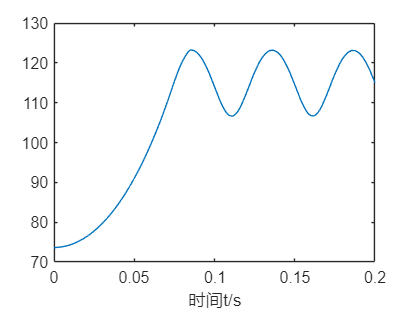

plot(Theta1(:,1),Theta1(:,2))
xlabel('时间t/s')
hold off



%计算相对误差
eq1=l_DE.*sind(theta1) - l_BC - l_CE.*sqrt(1 - ((s - l_DE.*cosd(theta1))./l_CE).^2 );
